
clc;
clear;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 比较 Nonapp, app, Combine CIO, BESTAnP, CRLB
% 在不同噪声强度下的RMSE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 设置环境变量，允许 OpenMP 运行时重复加载
setenv('KMP_DUPLICATE_LIB_OK', 'TRUE');  %防止报错

% 将此更改为你的脚本目录
py_path = 'C:\Users\Lenovo\Desktop\Matab Code\Experiments\test_numberpoint_influence'; 



%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 数据准备
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%旋转矩阵
% R_true= [0.4032    0.6640   0.6297;
%        0.5090   0.4092    -0.7573;
%       0.7605    -0.6258    0.1730];

R_true=[0.689673028293550	0.423447870703166	0.587403621746887
        0.176155229057263	0.688715772969376	-0.703306419236294
        -0.702367745073895	0.588525687510876	0.400396136119796];

%平移矢量
t_true = [2;3;4];
t_s_true = -R_true'*t_true;

num = [14];

stdVar_noise = [0.00001,0.00001,0.0001,0.001,0.01,0.1];

% stdVar_noise = [0.000001,0.00001,0.00001,0.0001,0.001,0.01,0.1];
% stdVar_noise = [0.1];

phi_max = 10*pi/180;
% 生成俯仰角 [-10°, 10°] 转换为弧度
elevation_angles = -phi_max + 2*phi_max*rand(num, 1);
% 生成俯仰角 [-10°, 10°] 转换为弧度
elevation_angles = deg2rad(-10 + 20*rand(1, num));
% 生成方位角 [-30°, 30°]
azimuth_angles = (-pi/6) + (pi/3) * rand(1, num);
% 生成距离 [0, 6] 米
d_true = 6 * rand(1, num);

% 生成 p_s
p_s(1,:)= (d_true .* cos(elevation_angles) .* cos(azimuth_angles));
p_s(2,:)= (d_true .* cos(elevation_angles) .* sin(azimuth_angles));
p_s(3,:)= (d_true .* sin(elevation_angles))';

% 生成 p_si
p_si(1,:)= d_true .* cos(azimuth_angles);
p_si(2,:)= d_true .* sin(azimuth_angles);

% 生成 p_w
p_w = R_true*p_s+t_true;



for n = 1:length(stdVar_noise)
    n
    % M = 1;
    M = 1000;

   
    % Wang's algorithm initial parameters
    error_t_App = 0;
    error_R_App = 0;

    error_t_combine_CIO = 0;
    error_R_combine_CIO = 0;
    

    error_t_Nonapp = 0;
    error_R_Nonapp = 0;

    % Our algorithm initial parameters
    error_t_BESTAnP = 0;
    error_R_BESTAnP = 0;

    error_t_initial = 0;
    error_R_initial = 0;

    error_t_initial_CIO = 0;
    error_R_initial_CIO = 0;
    

    for j = 1:M
        % --------------------
        % 噪声数据
        % --------------------
        % 生成噪声数据
        stdVar_noise_d = stdVar_noise(1,n);
        stdVar_noise_theta = stdVar_noise(1,n);
        
        d_noise = d_true + stdVar_noise_d*randn(1, num);
        
        noise_on_theta = stdVar_noise_theta*randn(1, num);

        %----------------------------------
        % 生成噪声数据 加在tan上、
        tan_theta = tan(azimuth_angles);
        tan_theta_noise = tan_theta + noise_on_theta;
        
        theta_noise_tan= atan(tan_theta_noise);
        
        cos_theta_noise_tan = cos(theta_noise_tan);
        sin_theta_noise_tan = sin(theta_noise_tan);
        p_si_noise = [d_noise.*cos_theta_noise_tan;d_noise.*sin_theta_noise_tan];



n = 1

n = 2

n = 3

n = 4

n = 5

n = 6

        
        % Wang's algorithm
        
        [R_app,t_app]=App_Algorithm(p_w,p_si_noise,phi_max,py_path);
        [R_Nonapp,t_Nonapp]=Nonapp_Algorithm(p_w,p_si_noise,phi_max,R_true,py_path);

        [R_combine_CIO,t_combine_CIO] = Combine_CIO(p_w,p_si_noise,phi_max,R_true,py_path);

        % My algorithm
        [R_BESTAnP,t_BESTAnP]=BESTAnP(p_w,p_si_noise);

        [R_initial,t_initial]=BESTAnP_initial_solution(p_w,p_si_noise);

        result_CIO = py.CIO.CIO(R_initial', -R_initial'*t_initial, p_w, p_si_noise, phi_max);
    
        R_CIO = double(result_CIO{1});
        t_CIO  = double(result_CIO{2})';
    
        R_initial_CIO  = R_CIO';
        t_initial_CIO  = -R_CIO'*t_CIO;

        %计算估计偏差 R
        s_app = rotm2eul(R_app*R_true','XYZ');
        s_combine_CIO =  rotm2eul(R_combine_CIO*R_true','XYZ');

        s_Nonapp =  rotm2eul(R_Nonapp*R_true','XYZ');
%         s_Nonapp_CIO = rotm2eul(R_Nonapp_CIO*R_true','XYZ');
        s_BESTAnP = rotm2eul(R_BESTAnP*R_true','XYZ');

        s_initial = rotm2eul(R_initial*R_true','XYZ');
        s_initial_CIO = rotm2eul(R_initial_CIO*R_true','XYZ');

        error_R_App = error_R_App + norm(s_app)^2;

        error_R_combine_CIO = error_R_combine_CIO + norm(s_combine_CIO)^2;
        
        error_R_Nonapp = error_R_Nonapp + norm(s_Nonapp)^2;
%         error_R_Nonapp_CIO = error_R_Nonapp_CIO + norm(s_Nonapp_CIO)^2;
        
        error_R_BESTAnP = error_R_BESTAnP + norm(s_BESTAnP)^2;

        error_R_initial = error_R_initial + norm(s_initial)^2;
        error_R_initial_CIO = error_R_initial_CIO + norm(s_initial_CIO)^2;

        %计算估计偏差 t
        error_t_App = error_t_App + norm(t_app-t_true)^2;
        error_t_combine_CIO = error_t_combine_CIO + norm(t_combine_CIO-t_true)^2;

        error_t_Nonapp = error_t_Nonapp + norm(t_Nonapp-t_true)^2;
%         error_t_Nonapp_CIO = error_t_Nonapp_CIO + norm(t_Nonapp_CIO-t_true)^2;

        error_t_BESTAnP = error_t_BESTAnP + norm(t_BESTAnP-t_true)^2;
        
        error_t_initial = error_t_initial + norm(t_initial-t_true)^2;
        error_t_initial_CIO = error_t_initial_CIO + norm(t_initial_CIO-t_true)^2;
    end

    [crlb_R,crlb_t] = Calculate_CRLB(p_w,R_true,t_true,stdVar_noise_d,stdVar_noise_theta);


    CRLB_t_x(n,:) = sqrt(crlb_t);
    CRLB_R_x(n,:) = sqrt(crlb_R);

    % Wang's algorithm
    Error_t_App(n,:) = sqrt(error_t_App/M);
    Error_R_App(n,:) = sqrt(error_R_App/M);

    Error_t_combine_CIO(n,:) = sqrt(error_t_combine_CIO/M);
    Error_R_combine_CIO(n,:) = sqrt(error_R_combine_CIO/M);


    Error_t_Nonapp(n,:) = sqrt(error_t_Nonapp/M);
    Error_R_Nonapp(n,:) = sqrt(error_R_Nonapp/M);

%     Error_t_Nonapp_CIO(n,:) = sqrt(error_t_Nonapp_CIO/M);
%     Error_R_Nonapp_CIO(n,:) = sqrt(error_R_Nonapp_CIO/M);


     % my algorithm
    Error_t_BESTAnP(n,:) = sqrt(error_t_BESTAnP/M);
    Error_R_BESTAnP(n,:) = sqrt(error_R_BESTAnP/M);

    Error_t_initial(n,:) = sqrt(error_t_initial/M);
    Error_R_initial(n,:) = sqrt(error_R_initial/M);

    Error_t_initial_CIO(n,:) = sqrt(error_t_initial_CIO/M);
    Error_R_initial_CIO(n,:) = sqrt(error_R_initial_CIO/M);
    

end

% figure
% plot(num,Error_t,'LineWidth', 2, 'Color', [0.20, 0.69, 0.28], 'Marker', 'p', 'MarkerSize', 5);
% xlabel('number');
% ylabel('error_t');
% 
% figure
% plot(num,Error_R,'LineWidth', 2, 'Color', [0.20, 0.69, 0.28], 'Marker', 'p', 'MarkerSize', 5);
% xlabel('number');
% ylabel('error_R');

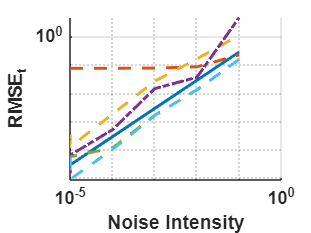


figure
grid on 
hold on;


loglog(stdVar_noise,CRLB_t_x,'LineWidth', 2,  'MarkerSize', 5);

% loglog(stdVar_noise,Error_t_initial,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(stdVar_noise,Error_t_App,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(stdVar_noise,Error_t_Nonapp,'--','LineWidth', 2, 'MarkerSize', 5);



loglog(stdVar_noise,Error_t_BESTAnP,'-.','LineWidth', 2,  'MarkerSize', 5);
loglog(stdVar_noise,Error_t_initial_CIO,'--','LineWidth', 2, 'MarkerSize', 5);


loglog(stdVar_noise,Error_t_combine_CIO,'--','LineWidth', 2, 'MarkerSize', 5);



% legend('CRLB','Initial CE','App','Nonapp','BESTAnP(CIO)','Combine+CIO','BESTAnP(GN)','FontSize', 12, 'FontWeight', 'bold','NumColumns', 2);
% legend('CRLB','Initial CEs','App','Nonapp','BESTAnP(GN)','BESTAnP(CIO)','Combined+CIO','FontSize', 12, 'FontWeight', 'bold','NumColumns', 2);
% legend('CRLB','App','Nonapp','BESTAnP','BESTAnP+CIO','Combined+CIO','FontSize', 12, 'FontWeight', 'bold','NumColumns', 2);

xlabel('Noise Intensity','FontSize', 12, 'FontWeight', 'bold');
ylabel('RMSE_t','FontSize', 12, 'FontWeight', 'bold');
set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');

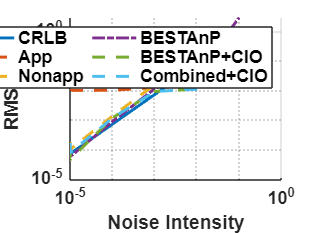

figure
grid on 
hold on;

loglog(stdVar_noise,CRLB_R_x,'LineWidth', 2,  'MarkerSize', 5);

% loglog(stdVar_noise,Error_R_initial,'--','LineWidth', 2, 'MarkerSize', 5);


loglog(stdVar_noise,Error_R_App,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(stdVar_noise,Error_R_Nonapp,'--','LineWidth', 2, 'MarkerSize', 5);
% loglog(num,Error_R_Nonapp_CIO,'-.','LineWidth', 2, 'MarkerSize', 5);



loglog(stdVar_noise,Error_R_BESTAnP,'-.','LineWidth', 2,  'MarkerSize', 5);
loglog(stdVar_noise,Error_R_initial_CIO,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(stdVar_noise,Error_R_combine_CIO,'--','LineWidth', 2, 'MarkerSize', 5);


% legend('CRLB','BESTAnP','App','Nonapp','Combine+CIO','FontSize', 12, 'FontWeight', 'bold');
% legend('CRLB','Initial CEs','App','Nonapp','BESTAnP(GN)','BESTAnP(CIO)','Combined+CIO','FontSize', 12, 'FontWeight', 'bold','NumColumns', 2);
legend('CRLB','App','Nonapp','BESTAnP','BESTAnP+CIO','Combined+CIO','FontSize', 12, 'FontWeight', 'bold','NumColumns', 2);


xlabel('Noise Intensity','FontSize', 12, 'FontWeight', 'bold');
ylabel('RMSE_R','FontSize', 12, 'FontWeight', 'bold');
set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');